# Analysis of Covid-19 WHO data

opts = weboptions;
opts.ContentType = 'table';
by_date = webread("https://opendata.ecdc.europa.eu/covid19/casedistribution/csv",opts);
by_date.Properties.VariableNames = ["date", "day", "month", "year", "cases", "deaths", "location", "geo_id", "code", "population"]

## Group by country 

[G,ID] = findgroups( by_date.location);

highlight = 1×4 cell array
    {'China'}    {'Italy'}    {'Spain'}    {'United_Kingdom'}


ID = categorical(ID);
by_country = table;
by_country.name = ID;

### Calculate Advanced Statistics

###  - Total cases & deaths

###  - 3 day rolling average

for n = 1:numel(ID)
    ix = find(G == n);
    by_date{ix,'total_deaths'}  = cumsum( by_date{ix,'deaths'}, 'reverse' );
    by_date{ix,'total_cases'}   = cumsum( by_date{ix,'cases'}, 'reverse' );
    by_date{ix,'mov_avg_deaths'}  = movmean( by_date{ix,'deaths'}, 3, 'Endpoints', 'fill' );
end
by_country.total_deaths = splitapply( @max, by_date.total_deaths, G );
by_country.total_cases = splitapply( @max, by_date.total_cases, G );

### Display latest date

latestDate = max(by_date.date)

### Find date of Nth death

N = 50;
by_country.date_deaths_N = splitapply( @(t,dt) findExeedanceDate(t,dt,N), by_date.date, by_date.total_deaths , G );

### Plot each country from date of Nth death

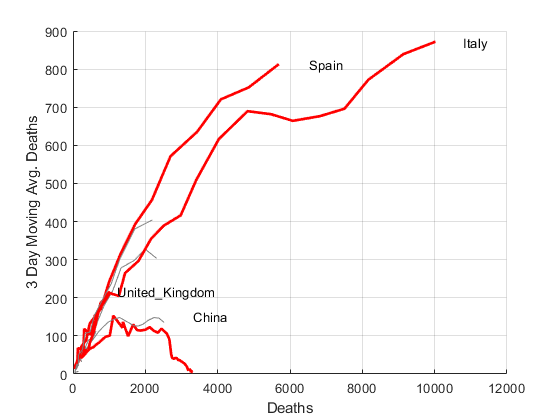

highlight = {'China' 'Italy' 'Spain' 'United_Kingdom'}

% Setup figure & axis
fig = figure; 
ax1 = axes("NextPlot","add","YScale","log");
grid on
xlabel(ax1,"Days since " + num2str(N) + "th death")
ylabel(ax1,'Total deaths')

fig = figure; 
ax2 = axes("NextPlot","add");
grid on
xlabel(ax2,"Days since " + num2str(N) + "th death")
ylabel(ax2,'3 Day Moving Avg. Deaths')

fig = figure; 
ax3 = axes("NextPlot","add");
grid on
xlabel(ax3,"Deaths")
ylabel(ax3,'3 Day Moving Avg. Deaths')

for id = ID'
    % Get single country summary
    country = by_country(by_country.name == id,:);
    
    % Index relevant data from main table
    ix = by_date.location == id & by_date.date >= country.date_deaths_N; 
    
    % Skip country if no relevant rows
    if ~any(ix); continue; end 
    
    % Calculate relative dates
    dt = by_date.date(ix) - country.date_deaths_N;
    total_deaths = by_date.total_deaths(ix);
    mov_avg_deaths = by_date.mov_avg_deaths(ix);
    
    % Plot rate of deaths
    y = total_deaths;
    if any(id == highlight)
        semilogy(ax1, dt, y, 'Color', 'red', 'LineWidth', 2)
        text(ax1, max(dt), max(y), strrep(char(id), '_', '\_'))
    else
        semilogy(ax1, dt, y, 'Color', [0.5 0.5 0.5])
    end
    
    % Plot moving average
    y = mov_avg_deaths;
    if any(id == highlight)
        plot(ax2, dt, y,'Color', 'red', 'LineWidth', 2)
        text(ax2, max(dt), max(y), strrep(char(id), '_', '\_'))

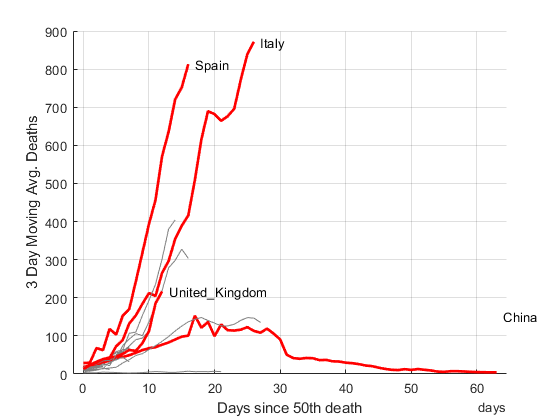

    else
        plot(ax2, dt, y, 'Color', [0.5 0.5 0.5])
    end
    

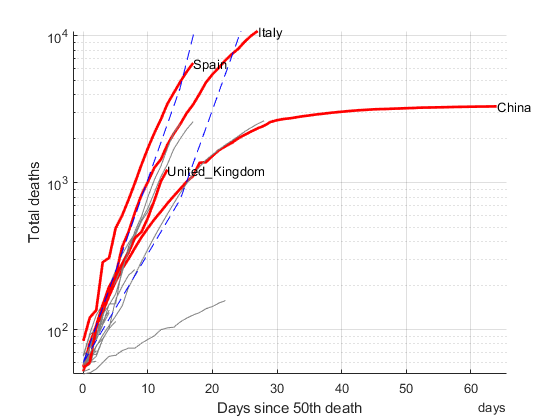

    % Plot moving average vs deaths
    x = total_deaths;
    y = mov_avg_deaths;
    if any(id == highlight)
        plot(ax3, x, y, 'Color', 'red', 'LineWidth', 2)
        text(ax3, max(x), max(y), strrep(char(id), '_', '\_'))
    else
        plot(ax3, x, y, 'Color', [0.5 0.5 0.5])
    end
    

end
% Get time base
X = ax1.XTick;
xtickformat(ax1,'d')
xtickformat(ax2,'d')
ax1.YLimMode = 'manual';
c = 'blue';

% Apply 33% growth line
Y = 10*(1.33).^days(X) + N;
semilogy(ax1, X, Y,'--','Color',c)

% Apply 50% growth line
Y = 10*(1.50).^days(X) + N;
semilogy(ax1, X, Y,'--','Color',c)

function dt = findExeedanceDate( dates, value, threshold )
[dates,ix] = sort(dates,'ascend');
value = value(ix);

ix = value >= threshold;
if any(ix)
    dt = dates( find(ix,1) );
else
    dt = NaT;
end
end